clear
focused = rgb2gray(acquireImage());
imshow(focused);

clearPixelVariance = var(var(focused))*10^5;

blurryPixelVariance = var(var(rgb2gray(acquireImage())))*10^5

%BLURRY
imageBlurry = rgb2gray(acquireImage());

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


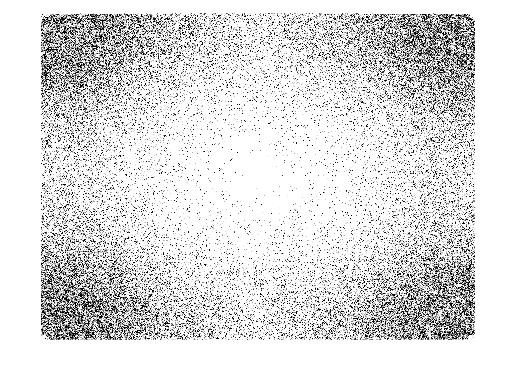

f = fft2(imageBlurry);
fsh = fftshift(f);
logTransformBlurry = log(abs(fsh));
imshow(logTransformBlurry);

blurryFFTVariance = var(var(logTransformBlurry))

blurryFFTVariance =         0.0405679738363812


%CLEAR
imageClear = rgb2gray(acquireImage());

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


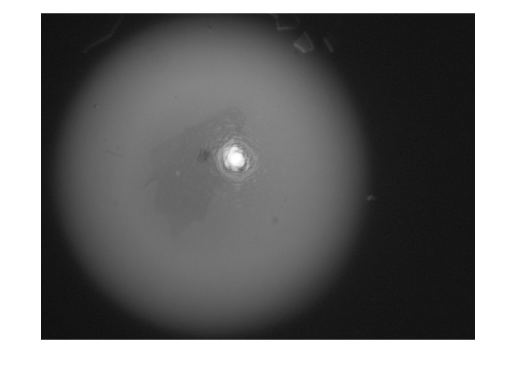

imshow(imageClear);

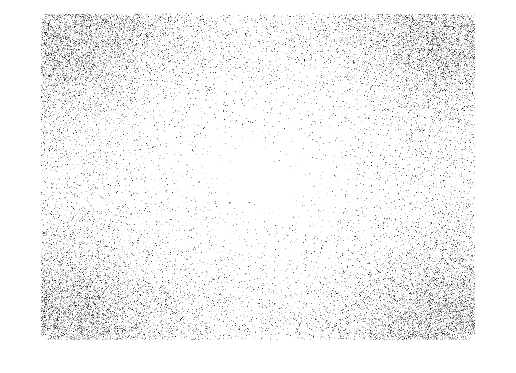

logTransformClear = log(abs(fftshift(fft2(imageClear))) + 1);
imshow(logTransformClear);

clearFFTVariance = var(var(logTransformClear))

clearFFTVariance =         0.0444384207556721
